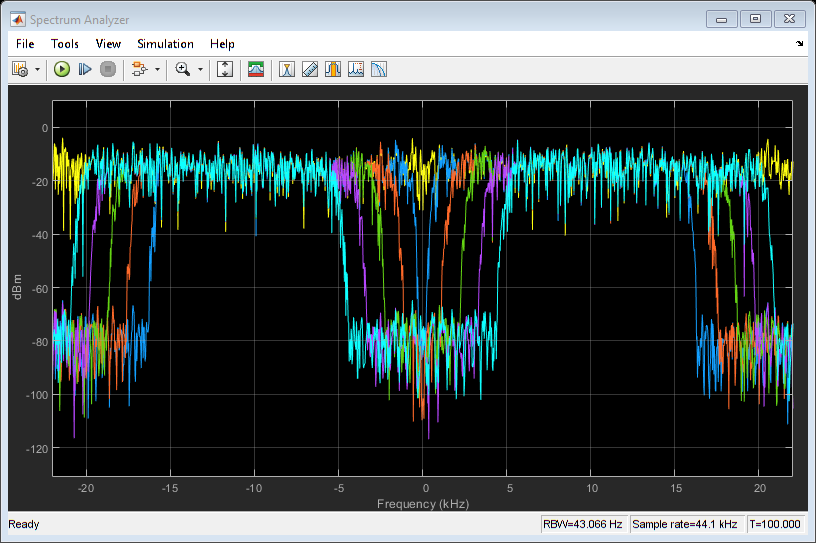

% Create and Load Data and Shape
% Noise Generation
set_param('Filter_Bank_Model/Gain1','Gain','0.00001');
sim('Filter_Bank_Model',100);

data = load('sig_noise_bw_iq.mat');
data = data.ans.Data;
data = reshape(data,[size(data,1)*size(data,3) 1]);
clip_index = rem(length(data), 1024);
data = data(1:length(data)-clip_index);
data = reshape(data, [1024 1 length(data)/1024]);
data_real = real(data);
data_imag = imag(data);
data_no_sig = [data_real data_imag];

% Signal Generation
set_param('Filter_Bank_Model/Gain1','Gain','0.08');
sim('Filter_Bank_Model',100);


data = load('sig_noise_bw_iq.mat');
data = data.ans.Data;
data = reshape(data,[size(data,1)*size(data,3) 1]);
clip_index = rem(length(data), 1024);
data = data(1:length(data)-clip_index);
data = reshape(data, [1024 1 length(data)/1024]);
data_real = real(data);
data_imag = imag(data);
data_sig = [data_real data_imag];



[train_data, train_label, test_data, test_label] = shuffle_data(data_sig, data_no_sig, 0.7);

% Deep Neural structure
% Add dropout layers later on to prevent overfitting! dropoutLayer(0.2)
layers = [
    imageInputLayer([1 1024 2], 'Name', 'Input')
    
    convolution2dLayer([1 8],16,'Padding','same', 'Name', 'Convolution 16')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer([1 2],'Stride',[1 2])
    
    convolution2dLayer([1 8],24,'Padding','same', 'Name', 'Convolution 24')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer([1 2],'Stride',[1 2])
    
    
    convolution2dLayer([1 8],32,'Padding','same', 'Name', 'Convolution 32')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer([1 2],'Stride',[1 2])  
    
    
    convolution2dLayer([1 8],48,'Padding','same', 'Name', 'Convolution 48')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer([1 2],'Stride',[1 2])
 
    
    convolution2dLayer([1 8],64,'Padding','same', 'Name', 'Convolution 64')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer([1 2],'Stride',[1 2])
    
    
    convolution2dLayer([1 8],96,'Padding','same', 'Name', 'Convolution 96')
    batchNormalizationLayer
    reluLayer
    averagePooling2dLayer([1 32], 'Stride', 1)
    
    fullyConnectedLayer(20, 'Name', 'Fully Connected 20')
    fullyConnectedLayer(10, 'Name', 'Fully Connected 10')
    fullyConnectedLayer(2, 'Name', 'Fully Connected 2')
    
    softmaxLayer
    classificationLayer];


options = trainingOptions('adam', ...
    'InitialLearnRate',0.02, ...
    'Verbose',false, ...
    'Plots','training-progress', ...
    'MaxEpochs', 5);


trainedNet_sim = trainNetwork(train_data,train_label,layers,options);

save trainedNet_sim

% Test Neural network with test data
predLabels = trainedNet_sim.classify(test_data);
P_d = sum(test_label == predLabels)/length(predLabels)*100

P_d = 82.6306

function [train_data, train_label, test_data, test_label] = shuffle_data(sig_frames, no_sig_frames, train_test_split)
    sig_size = size(sig_frames);
    no_sig_size = size(no_sig_frames);
    min_size = min(sig_size(3),no_sig_size(3));
    
    shuffled_data = zeros(1,sig_size(1),sig_size(2),min_size);
    labels = zeros(min_size,1);
    
    for i = 1:min_size
        even_index = 2*i;
        odd_index = 2*i-1;
        shuffled_data(1,:,:,even_index) = sig_frames(:,:,i);
        shuffled_data(1,:,:,odd_index) = no_sig_frames(:,:,i);
        
        labels(even_index,1) = 1;
        labels(odd_index,1) = 0;
    end
    train_index = round(train_test_split*min_size*2);
    
    train_data = shuffled_data(:,:,:,1:train_index);
    test_data = shuffled_data(:,:,:,train_index:end);
    train_label = categorical(labels(1:train_index,:));
    test_label = categorical(labels(train_index:end,:));
end